%% ── Fill in these parameters ──────────────────────────────────────────────
geom.wing_span    = 1.2;   % [m]   full wing span
geom.wing_AR      = 4;   % [-]   wing aspect ratio
geom.htail_span   = 0.4;   % [m]   full horizontal tail span
geom.htail_AR     = 3;   % [-]   horizontal tail aspect ratio
geom.htail_incidence = -2;   % [deg] horizontal tail incidence (negative = trailing edge up, e.g. -2.0)
geom.vtail_height = 0.2;   % [m]   vertical tail height
geom.vtail_AR     = 2;   % [-]   vertical tail aspect ratio
geom.tail_arm     = 0.85;   % [m]   AC-to-AC tail moment arm
geom.nose_x       = 0.25;   % [m]   motor+prop x-position from wing LE (negative = forward)
geom.n_ducks      = 3;   % [-]   number of duck payloads
geom.n_pucks      = 1;   % [-]   number of puck payloads

% Reversing for conventions
geom.nose_x = -1 * geom.nose_x;
geom.htail_incidence = -1 * geom.htail_incidence;

% Building mass layout from geometries
mass = defineMassConfig(geom);


=== Mass Breakdown ===
  Component             m (kg)    x (m)    z (m)
  ------------------------------------------------
  Wing                   0.730   +0.135  +0.0000
  Htail                  0.072   +0.952  +0.0000
  Vtail                  0.027   +0.937  +0.0000
  Tail spar              0.183   +0.446  +0.0000
  Fuselage               0.430   +0.025  +0.0000
  Motor+Prop             0.390   -0.350  -0.0250
  Nosecone               0.152   -0.210  +0.0000
  Battery                0.690   -0.150  -0.0250
  Receiver               0.024   -0.100  +0.0000
  Servo bat.             0.045   -0.120  +0.0000
  Gyro                   0.021   -0.130  +0.0000
  Main gear              0.125   +0.120  -0.0250
  Front gear             0.105   -0.125  -0.0250
  3 Duck(s)              0.348   +0.191  +0.0000
  1 Puck(s)              0.190   +0.084  +0.0000
  ------------------------------------------------
  TOTAL / CG             3.531  +0.0244  -0.0093

  CG: 0.0244 m = 8.1% MAC
  Ixx = 0.0890

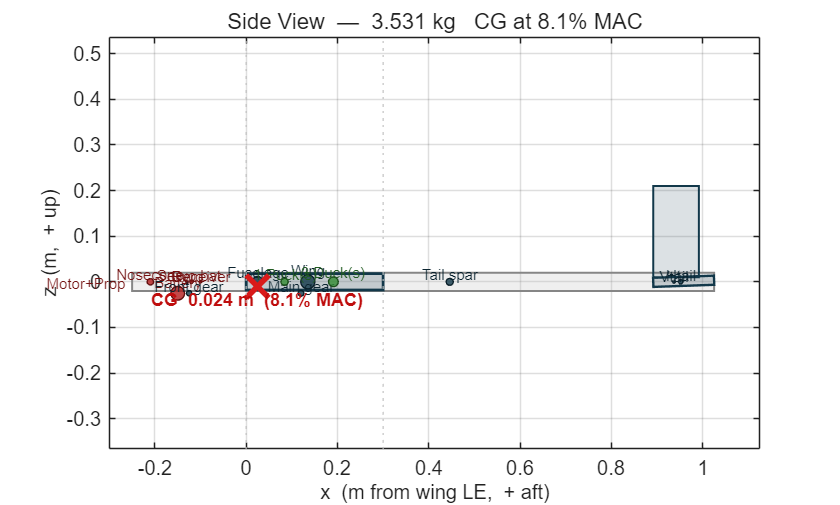

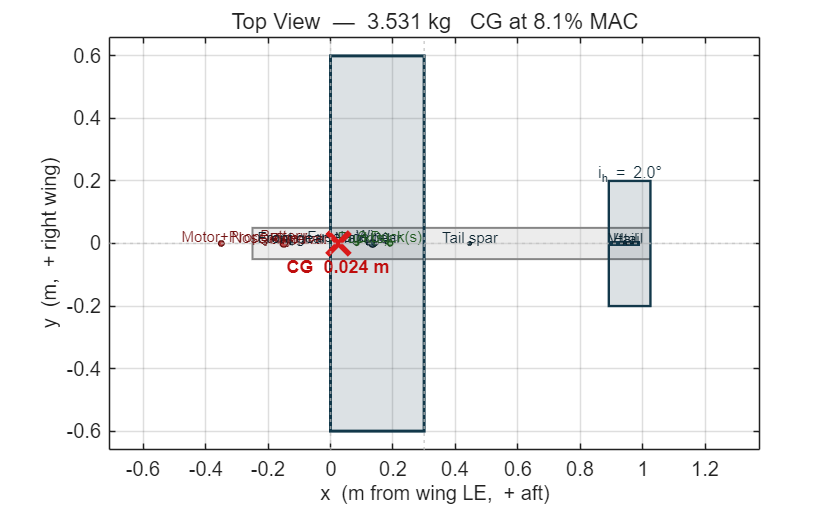

 
plotMassLayout(mass);

V = 27;
aircraft = massToAVL(mass);         % AVL-ready struct


=== Aircraft Config ===
  Wing:    span = 1.200 m   chord = 0.3000 m   AR = 4.00   S = 0.3600 m²
  Htail:   span = 0.400 m   chord = 0.1333 m   x_le = 0.8917 m
  Vtail:   h    = 0.250 m   chord = 0.1250 m   x_le = 0.8917 m
  Tail arm = 0.8500 m   Vht = 0.420   Vvt = 0.061
  Mass     = 3.547 kg
  CG       = 0.0394 m (13.1% MAC)


out      = runAVL(aircraft, V);     % run AVL

Flight condition:
  V         = 27.00 m/s
  rho       = 1.2250 kg/m3
  mass      = 3.547 kg
  CL_cruise = 0.2164
AVL geometry file written: C:\Users\kaspe\OneDrive\Cornell\All\Coding\end-of-semester-25-26\src\avl\dfo.avl
Open in AVL with:  load C:\Users\kaspe\OneDrive\Cornell\All\Coding\end-of-semester-25-26\src\avl\dfo.avl
Then view with:    oper -> g
Mass file written: C:\Users\kaspe\OneDrive\Cornell\All\Coding\end-of-semester-25-26\src\avl\dfo.mass
Running AVL...
Done. Output files:
  Stability: C:\Users\kaspe\OneDrive\Cornell\All\Coding\end-of-semester-25-26\src\avl\dfo_stability.txt
  AVL log:   C:\Users\kaspe\OneDrive\Cornell\All\Coding\end-of-semester-25-26\src\avl\avl_log.txt


avl      = parseAVLOutput(out.stability_file);


=== AVL Results ===
  Trim alpha     = -1.052 deg
  Trim elevator  = -3.570 deg
  CL             =  0.2164
  CDi (Trefftz)  =  0.00387  [induced only -- CD0 from sizing script]
  Span eff. e    =  NaN
  Neutral pt Xnp =  0.1098 m

  --- Pitch ---
  CLa  = +3.7970 /rad
  Cma  = -0.0008 /rad   (< 0 = stable)
  Cmq  = -7.1461 /rad

  --- Lateral/Directional ---
  Clb  = -0.0279 /rad
  Cnb  = +0.1429 /rad   (> 0 = weathercock stable)
  Clp  = -0.3512 /rad   (roll damping)
  Cnr  = -0.2113 /rad   (yaw  damping)
  Spiral ratio   =  0.406  (> 1 = spirally stable)


modes    = computeAVLModes(avl, aircraft, V);


=== Flight Dynamics Modes ===
  Phugoid         σ = -0.0272   ω = +0.0121 rad/s   [stable]
  Short Period    σ = -4.3659   (non-oscillatory)   [stable]
  Dutch Roll      σ = -1.1634   ω = +7.9810 rad/s   [stable]
  Roll            σ = -485.6885   (non-oscillatory)   [stable]
  Spiral          σ = +0.0622   (non-oscillatory)   t2 = 11.14 s  [UNSTABLE]


## Longitudinal Stability

There are two types of stability modes: longitudinal, which focuses on

the pitch of the aircraft, and lateral, which accounts for yaw and roll.

What do we mean by mode? Modes are natural motions the aircraft can go

through during flight. For example, if you push a swing it will move up

and down until settling down — that's one mode. Planes have six! How we

derive these is a long and arduous process, but what matters to us is

whether or not they're stable. Imagine if your friend pushed you on a

swing and you started gaining more and more speed until eventually the

swing just broke. Yep. That's not good for planes either.

To visualize modes, we plot eigenvalues on the complex plane. Anything in the left half (negative real part) is stable. Anything in the right half is not.

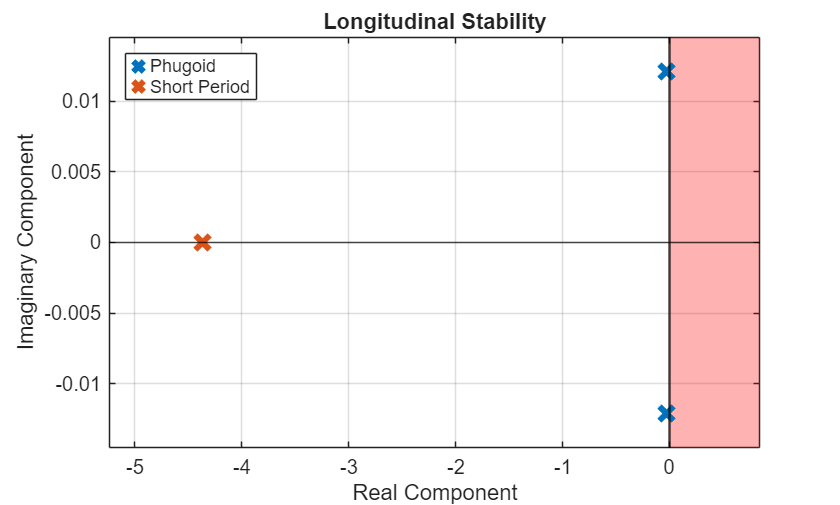

lon_modes  = {'Phugoid', 'ShortPeriod'};
lon_labels = {'Phugoid', 'Short Period'};

% Compute axis limits from actual mode values before drawing anything
all_sig = cellfun(@(k) modes.(k).sigma, lon_modes);
all_omg = cellfun(@(k) abs(modes.(k).omega), lon_modes);
pad_x = max(abs(all_sig)) * 0.2;
pad_y = max(all_omg) * 0.2;
xl = [min(all_sig) - pad_x,  max(all_sig) + pad_x];
yl = [-(max(all_omg) + pad_y), max(all_omg) + pad_y];

figure;
hold on;

patch([0, xl(2), xl(2), 0], [yl(1), yl(1), yl(2), yl(2)], ...
    [1 0 0], 'EdgeColor', 'none', 'FaceAlpha', 0.3, 'HandleVisibility', 'off')

yline(0, 'k', 'LineWidth', 0.8,  'HandleVisibility', 'off')
xline(0, 'k', 'LineWidth', 1.2,  'HandleVisibility', 'off')

for k = 1:numel(lon_modes)
    m   = modes.(lon_modes{k});
    col = [0.07 0.22 0.29];
    if m.sigma > 0, col = [0.70 0.11 0.11]; end

    if abs(m.omega) > 0.01
        plot([m.sigma, m.sigma], [m.omega, -m.omega], 'x', ...
            'MarkerSize', 10, 'LineWidth', 3, 'Color', '#0072BE', 'DisplayName', lon_labels{k})
    else
        plot(m.sigma, 0, 'x', ...
            'MarkerSize', 10, 'LineWidth', 3, 'Color', '#DA5319', 'DisplayName', lon_labels{k})
    end
end

xlim(xl); ylim(yl);
xlabel('Real Component');  ylabel('Imaginary Component');
title('Longitudinal Stability');
legend('Location', 'northwest');
grid on; box on; hold off;

% Lateral Stability

In the lateral plots, you'll notice that some modes only have one

eigenvalue displayed — they are purely real. If you've suffered through

PHYS 2214 Waves, you'll recall that means these values do not oscillate

and either exponentially decay or grow. It's here we're most likely to

see an instability in the spiral mode. Zoom in on the origin to check

whether the spiral sits just barely in the positive x-domain.

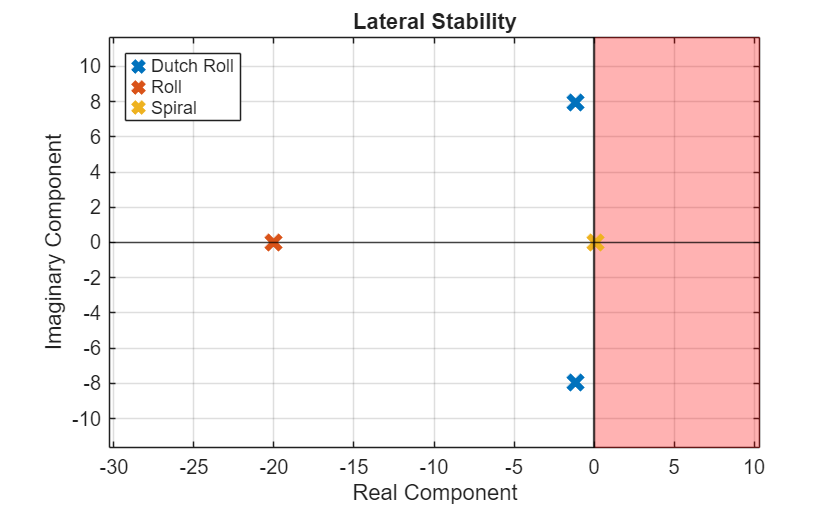

lat_modes  = {'DutchRoll', 'Roll', 'Spiral'};
lat_labels = {'Dutch Roll', 'Roll', 'Spiral'};
colors = {'#0072BD', '#D95319', '#EEB220'}; % default blue, red, your yellow

% Clamp roll mode for axis scaling only — it's always far-left and stable
clamp = 20;
all_sig_lat = cellfun(@(k) max(modes.(k).sigma, -clamp), lat_modes);
all_omg_lat = cellfun(@(k) abs(modes.(k).omega), lat_modes);
pad_x = max(abs(all_sig_lat)) * 0.5 + 0.3;
pad_y = max(all_omg_lat) * 0.4 + 0.5;
xl2 = [min(all_sig_lat) - pad_x,  max(all_sig_lat) + pad_x];
yl2 = [-(max(all_omg_lat) + pad_y), max(all_omg_lat) + pad_y];

figure;
hold on;

patch([0, xl2(2), xl2(2), 0], [yl2(1), yl2(1), yl2(2), yl2(2)], ...
    [1, 0, 0], 'EdgeColor', 'none', 'FaceAlpha', 0.3, 'HandleVisibility', 'off')

yline(0, 'k', 'LineWidth', 0.8,  'HandleVisibility', 'off')
xline(0, 'k', 'LineWidth', 1.2,  'HandleVisibility', 'off')

for k = 1:numel(lat_modes)
    m    = modes.(lat_modes{k});
    col  = [0.07 0.22 0.29];
    if m.sigma > 0, col = [0.70 0.11 0.11]; end
    % Plot at clamped x if roll is off-scale, with a note
    sig_plot = max(m.sigma, -clamp);
    if abs(m.omega) > 0.01
        plot([sig_plot, sig_plot], [m.omega, -m.omega], 'x', ...
            'MarkerSize', 10, 'LineWidth', 3, 'Color', colors{k}, 'DisplayName', lat_labels{k})
    else
        plot(sig_plot, 0, 'x', ...
            'MarkerSize', 10, 'LineWidth', 3, 'Color', colors{k}, 'DisplayName', lat_labels{k})
        % if m.sigma < -clamp
        %     text(sig_plot, 0.15, sprintf('σ=%.0f', m.sigma), ...
        %         'FontSize', 8, 'Color', colors{k}, 'HorizontalAlignment', 'center')
        % end
    end
end

xlim(xl2); ylim(yl2);
xlabel('Real Component');  ylabel('Imaginary Component');
title('Lateral Stability');
legend('Location', 'northwest');
grid on; box on; hold off;

% Doubling Times

One other consideration is the doubling time. If a mode is unstable, we

want to measure how long it takes for the instability to grow. If it

grows very slowly, that's okay — Mitch can just fix it in flight. If it

doubles much quicker than a reaction time can allow, that's when we have

a problem.


mode_names   = {'Phugoid', 'ShortPeriod', 'DutchRoll', 'Roll', 'Spiral'};
label_names  = {'Phugoid', 'Short Period', 'Dutch Roll', 'Roll', 'Spiral'};

unstable_labels = {};
unstable_t2     = [];

for k = 1:numel(mode_names)
    m = modes.(mode_names{k});
    if isfinite(m.t2)
        fprintf('Mode: %-14s  t2 = %.3f s\n', label_names{k}, m.t2)
        unstable_labels{end+1} = label_names{k};
        unstable_t2(end+1)     = m.t2;
    end
end

Mode: Spiral          t2 = 11.138 s


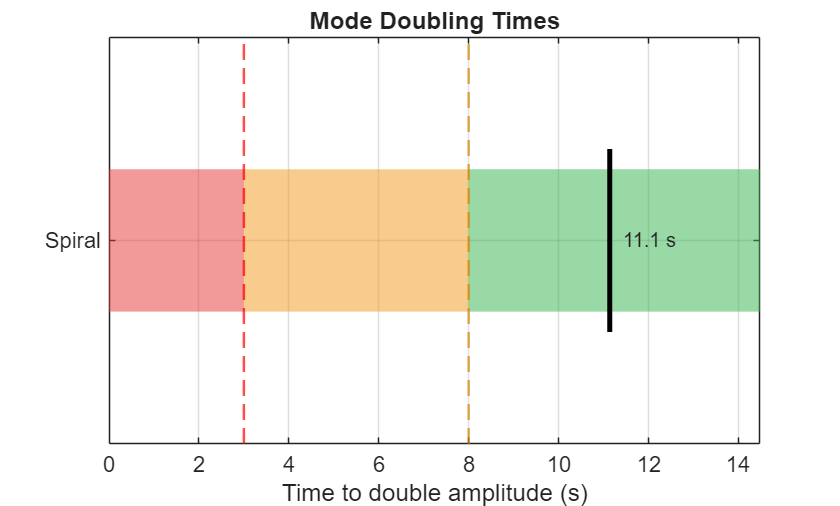


if isempty(unstable_labels)
    fprintf('All modes are stable — no doubling times to report.\n')
end

if ~isempty(unstable_labels)
    figure;
    hold on;
    title('Mode Doubling Times')
    xlabel('Time to double amplitude (s)')

    x_max = max(max(unstable_t2) * 1.3, 12);
    bar_h = 0.35;

    for k = 1:numel(unstable_labels)
        t2 = unstable_t2(k);
        y  = [k-bar_h/2, k-bar_h/2, k+bar_h/2, k+bar_h/2];

        patch([0, min(3,x_max), min(3,x_max), 0], y, ...
              [0.90 0.20 0.20], 'FaceAlpha', 0.5, 'EdgeColor', 'none', 'HandleVisibility', 'off')
        if x_max > 3
            patch([3, min(8,x_max), min(8,x_max), 3], y, ...
                  [0.95 0.60 0.10], 'FaceAlpha', 0.5, 'EdgeColor', 'none', 'HandleVisibility', 'off')
        end
        if x_max > 8
            patch([8, x_max, x_max, 8], y, ...
                  [0.20 0.70 0.30], 'FaceAlpha', 0.5, 'EdgeColor', 'none', 'HandleVisibility', 'off')
        end

        plot([t2 t2], [k-bar_h/2-0.05, k+bar_h/2+0.05], ...
             'k-', 'LineWidth', 2.5, 'HandleVisibility', 'off')
        text(t2 + x_max*0.02, k, sprintf('%.1f s', t2), ...
             'VerticalAlignment', 'middle', 'FontSize', 10)
    end

    xline(3, 'r--', 'LineWidth', 1.2, 'HandleVisibility', 'off')
    xline(8, '--', 'Color', [0.85 0.50 0.0], 'LineWidth', 1.2, 'HandleVisibility', 'off')

    set(gca, 'YTick', 1:numel(unstable_labels), ...
             'YTickLabel', unstable_labels, 'FontSize', 11)
    xlim([0 x_max])
    ylim([0.5, numel(unstable_labels) + 0.5])
    grid on; box on;
    hold off;
end